  %Factor de escala (1 - 1.3)
F=1

F = 1

R = 7                                  %Rotación (-pi/2 - pi/2)

R = 7

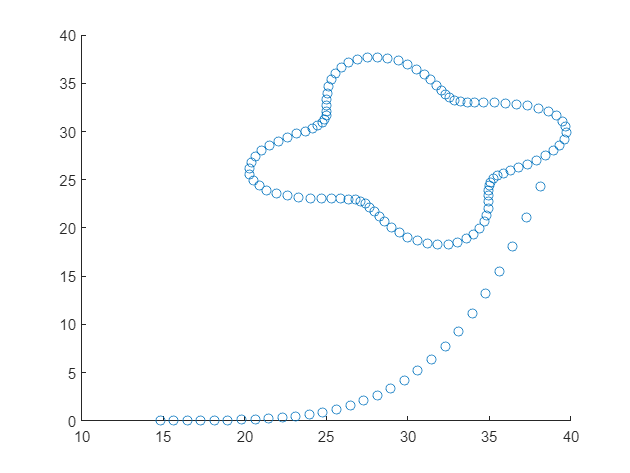

R=rad2deg(R);
L1 = 30;
L2 = 26;
TiempoSimulacion=10;
repeticiones=10;                        %Número de repeticiones del trebol
r = @(x) F*(2*sin(4.*(x+R)-pi/2)+8);    %Función polar del trebol
N_puntos = 100;                         %Número de puntos
n = 0:N_puntos-1;                       %Vector de puntos
theta = n*2*pi/N_puntos;                %Vector de angulo

%trayectoria de aproximación
pntN=30;
n_aprox=linspace(14.8,r(0)+30,pntN);       
f_aprox= ((28-0.05)/(r(0)+30-14.8)^4)*(n_aprox-14.8).^4+0.05;

P_x1 = r(theta).*cos(theta)+30;          %Coordenadas en x del trebol
P_y1 = r(theta).*sin(theta)+28;          %Coordenadas en y del trebol 
P_x = [n_aprox P_x1(2:length(P_x1))];     %Concatenar trayectoria de aproximación con trebol
P_y = [f_aprox P_y1(2:length(P_y1))];     %Concatenar trayectoria de aproximación con trebol
scatter(P_x,P_y)


theta_2 = pi+acos((P_x.^2+P_y.^2-L1^2-L2^2)/(2*L1*L2));
theta_1 = 3*pi/2+atan(P_y./P_x)+atan((L2*sin(theta_2))./(L1+L2*cos(theta_2)));


theta_2D= rad2deg(theta_2)

theta_2D =   330.4406  328.6048  326.7676  324.9274  323.0829  321.2327  319.3756  317.5104  315.6356  313.7496  311.8502  309.9346  307.9989  306.0376  304.0430  302.0049  299.9091  297.7370  295.4636  293.0566  290.4743  287.6633  284.5556  281.0651  277.0817  272.4632  267.0205  260.4896  252.4716  242.2805  239.6050  237.1483  235.0642  233.4962  232.5551  232.2983  232.7166  233.7346  235.2253  237.0322  238.9906  240.9449  242.7592  244.3244  245.5615  246.4232  246.8945  246.9922  246.7624  246.2779


theta_1D= rad2deg(theta_1)

theta_1D =   256.4935  255.6358  254.7811  253.9329  253.0972  252.2816  251.4953  250.7482  250.0515  249.4167  248.8556  248.3804  248.0029  247.7346  247.5859  247.5659  247.6819  247.9381  248.3351  248.8683  249.5267  250.2916  251.1338  252.0124  252.8722  253.6410  254.2269  254.5141  254.3584  253.5890  252.9131  252.4572  252.2614  252.3482  252.7212  253.3654  254.2499  255.3307  256.5533  257.8554  259.1729  260.4454  261.6227  262.6697  263.5686  264.3194  264.9382  265.4536  265.9032  266.3282


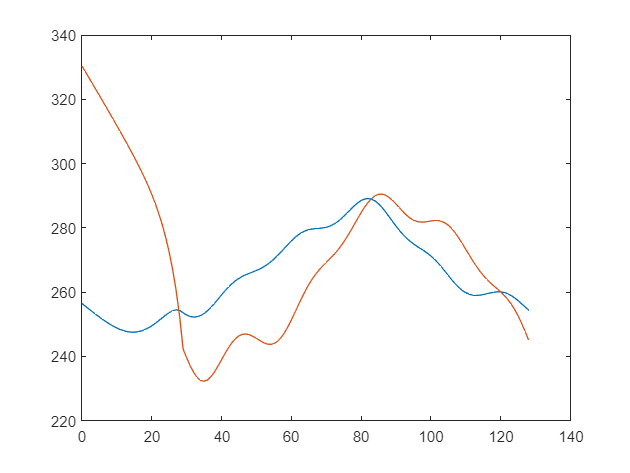


n2=0:N_puntos-1+pntN-1;
figure()
plot(n2,theta_1D) %Azul
hold on
plot(n2,theta_2D) %Roja
hold off


%Implementación de repeticiones

for i=1:1:repeticiones-1
   P_x=[P_x P_x1];
   P_y=[P_y P_y1];
end

%Trayectorias ya con repetición
rtheta_2 = pi+acos((P_x.^2+P_y.^2-L1^2-L2^2)/(2*L1*L2))

rtheta_2 =     5.7673    5.7352    5.7032    5.6711    5.6389    5.6066    5.5742    5.5416    5.5089    5.4760    5.4428    5.4094    5.3756    5.3414    5.3066    5.2710    5.2344    5.1965    5.1568    5.1148    5.0697    5.0207    4.9664    4.9055    4.8360    4.7554    4.6604    4.5464    4.4065    4.2286    4.1819    4.1390    4.1026    4.0753    4.0589    4.0544    4.0617    4.0794    4.1055    4.1370    4.1712    4.2053    4.2369    4.2643    4.2859    4.3009    4.3091    4.3108    4.3068    4.2984


rtheta_1 = 3*pi/2+atan(P_y./P_x)+atan((L2*sin(rtheta_2))./(L1+L2*cos(rtheta_2)))

rtheta_1 =     4.4767    4.4617    4.4468    4.4320    4.4174    4.4031    4.3894    4.3764    4.3642    4.3531    4.3434    4.3351    4.3285    4.3238    4.3212    4.3208    4.3229    4.3273    4.3343    4.3436    4.3551    4.3684    4.3831    4.3984    4.4135    4.4269    4.4371    4.4421    4.4394    4.4260    4.4142    4.4062    4.4028    4.4043    4.4108    4.4221    4.4375    4.4564    4.4777    4.5004    4.5234    4.5456    4.5662    4.5845    4.6001    4.6132    4.6240    4.6330    4.6409    4.6483



rtheta_2D= rad2deg(rtheta_2)

rtheta_2D =   330.4406  328.6048  326.7676  324.9274  323.0829  321.2327  319.3756  317.5104  315.6356  313.7496  311.8502  309.9346  307.9989  306.0376  304.0430  302.0049  299.9091  297.7370  295.4636  293.0566  290.4743  287.6633  284.5556  281.0651  277.0817  272.4632  267.0205  260.4896  252.4716  242.2805  239.6050  237.1483  235.0642  233.4962  232.5551  232.2983  232.7166  233.7346  235.2253  237.0322  238.9906  240.9449  242.7592  244.3244  245.5615  246.4232  246.8945  246.9922  246.7624  246.2779


rtheta_1D= rad2deg(rtheta_1)

rtheta_1D =   256.4935  255.6358  254.7811  253.9329  253.0972  252.2816  251.4953  250.7482  250.0515  249.4167  248.8556  248.3804  248.0029  247.7346  247.5859  247.5659  247.6819  247.9381  248.3351  248.8683  249.5267  250.2916  251.1338  252.0124  252.8722  253.6410  254.2269  254.5141  254.3584  253.5890  252.9131  252.4572  252.2614  252.3482  252.7212  253.3654  254.2499  255.3307  256.5533  257.8554  259.1729  260.4454  261.6227  262.6697  263.5686  264.3194  264.9382  265.4536  265.9032  266.3282


rN_puntos=N_puntos*repeticiones

rN_puntos = 1000

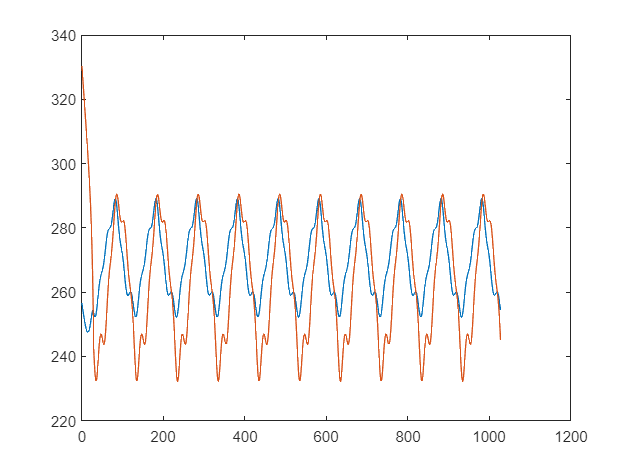

n3=0:(rN_puntos)-1+pntN-1;
figure()
plot(n3,rtheta_1D) %Azul
hold on
plot(n3,rtheta_2D) %Roja
hold off

IMPLEMENTACIÓN EN SIMSCAPE PARA VER LA TRAYECTORIA SIN CONTROL.

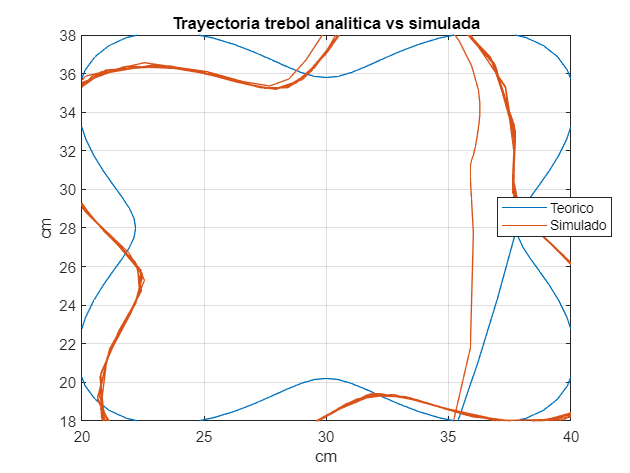


tiempo=10;
t= linspace(0,tiempo,length(n)+pntN-1)';
q1=[t, theta_1'];
q2=[t, theta_2'];
% %Ejecución de simulación
sim("Robot.slx");

%Graficar posiciones en XYZ con objeto timpo TimeSeries en el sensor
% plot(out.xf);
% hold on
% plot(t, ((P_x)/100)+0.1);
% hold off
% plot(out.yf);
% hold on
% plot(t, (P_y/100)+0.2);
% hold off
%Grafica de las dos trayectorias
plot((P_x),(P_y));
hold on
plot((out.xf*100)-10.5,(out.yf*100)-22);
hold off

xlim([20.0 40.0])
ylim([18.0 38.0])
grid on
legend(["Teorico","Simulado"])
legend("Position",[0.78946,0.50111,0.18214,0.082143])
title("Trayectoria trebol analitica vs simulada")
xlabel("cm")
ylabel("cm")

## Definición de perfiles de velocidad, aceleración y torque

% Se hace cada perfil suponiendo una velocidad de recorrido entre los puntos definidos anteriormente para los ángulos, 
% se toma el perimetro como un cuadrado constante y de allí se calculan los tiempos a usar entre punto y punto
vel=6

vel = 6

PerMax=15*4*1.3;
%Tiempo entre cambio de posición
temp=(PerMax)/(vel*(N_puntos+pntN-1));
%Determinación de vector tiempo
Tmpv=0:temp:(temp*(rN_puntos-1+pntN-1));
Ajuste=zeros(1,1);
TiempoSimulacion=max(Tmpv);
%Determinacion de vectores de velocidad

w1=diff(rtheta_1)/temp;
w1=[Ajuste w1]

w1 =          0   -0.1304   -0.1299   -0.1287   -0.1264   -0.1227   -0.1173   -0.1100   -0.1006   -0.0891   -0.0752   -0.0591   -0.0406   -0.0200    0.0028    0.0273    0.0533    0.0801    0.1072    0.1335    0.1578    0.1786    0.1940    0.2018    0.1994    0.1840    0.1521    0.1000    0.0231   -0.0842   -0.0086   -0.0411   -0.0687   -0.0889   -0.0998   -0.1001   -0.0895   -0.0682   -0.0375    0.0004    0.0424    0.0853    0.1264    0.1635    0.1947    0.2180    0.2317    0.2350    0.2285    0.2140


w2=diff(rtheta_2)/temp;
w2=[Ajuste w2]

w2 =          0   -0.2790   -0.2792   -0.2795   -0.2800   -0.2807   -0.2816   -0.2826   -0.2837   -0.2852   -0.2869   -0.2891   -0.2919   -0.2957   -0.3008   -0.3076   -0.3169   -0.3295   -0.3464   -0.3689   -0.3987   -0.4377   -0.4882   -0.5532   -0.6362   -0.7420   -0.8771   -1.0514   -1.2818   -1.6008   -0.1694   -0.2284   -0.2898   -0.3485   -0.3987   -0.4349   -0.4514   -0.4431   -0.4059   -0.3378   -0.2402   -0.1189    0.0150    0.1478    0.2659    0.3593    0.4227    0.4555    0.4602    0.4410


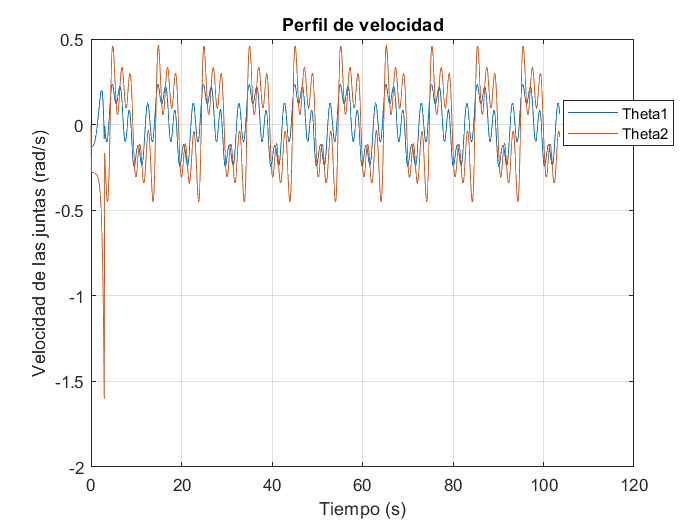


%Grafico velocidad v=6cm/s por defecto se puede cambiar en el variador
plot(Tmpv,w1);
hold on
plot(Tmpv,w2);
hold off

xlim("auto")
ylim("auto")
grid on
legend(["Theta1","Theta2"])
title("Perfil de velocidad")
xlabel("Tiempo (s)")
ylabel("Velocidad de las juntas (rad/s)")


%Se usará finalmente el perfil de 6cm/s que determinará un buen desempeño,
%tanto de velocidad como precisión

%calculo de perfil de aceleración para la velocidad de 6cm/s

a1=diff(w1)/temp;
a1=[Ajuste a1]

a1 =          0   -1.2936    0.0048    0.0117    0.0226    0.0368    0.0536    0.0725    0.0930    0.1148    0.1374    0.1603    0.1830    0.2050    0.2255    0.2434    0.2577    0.2667    0.2685    0.2609    0.2412    0.2063    0.1529    0.0775   -0.0235   -0.1535   -0.3163   -0.5169   -0.7630   -1.0646    0.7503   -0.3228   -0.2741   -0.2005   -0.1080   -0.0035    0.1057    0.2114    0.3046    0.3756    0.4168    0.4261    0.4079    0.3682    0.3093    0.2310    0.1359    0.0329   -0.0645   -0.1437


a2=diff(w2)/temp;
a2=[Ajuste a2]

a2 =          0   -2.7687   -0.0016   -0.0035   -0.0051   -0.0067   -0.0083   -0.0099   -0.0118   -0.0141   -0.0173   -0.0218   -0.0282   -0.0373   -0.0502   -0.0680   -0.0922   -0.1248   -0.1678   -0.2237   -0.2955   -0.3867   -0.5013   -0.6446   -0.8238   -1.0498   -1.3407   -1.7300   -2.2859   -3.1659   14.2040   -0.5856   -0.6096   -0.5819   -0.4988   -0.3590   -0.1638    0.0824    0.3690    0.6759    0.9692    1.2028    1.3290    1.3178    1.1722    0.9266    0.6296    0.3256    0.0460   -0.1908


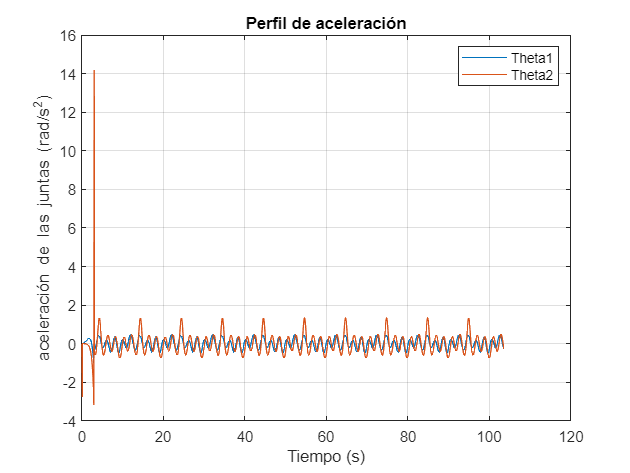


plot(Tmpv,a1)
hold on
plot(Tmpv,a2)
hold off

xlim("auto")
ylim("auto")
grid on
legend(["Theta1","Theta2"])
title("Perfil de aceleración")
xlabel("Tiempo (s)")
ylabel("aceleración de las juntas (rad/s^2)")

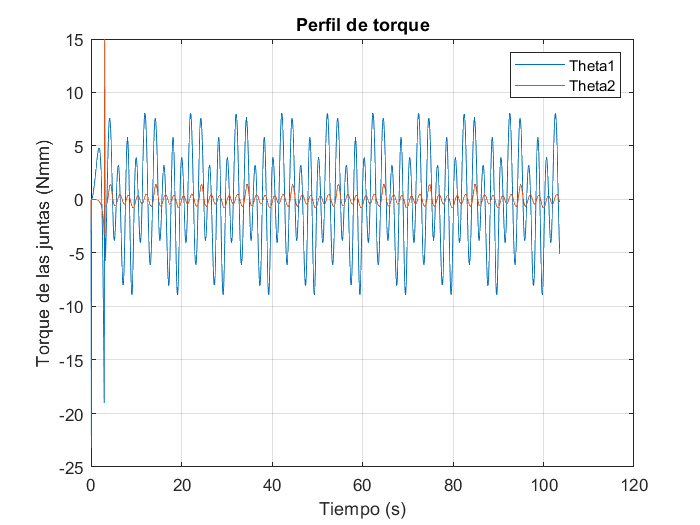


%Calculo de inercia y calculo de perfil de torque
M1=(52540.825/(10^3))*(1.24)/1000; %Volumen encontrado en inventor, densidad del PLA 1.24 g/cm^3 y conversión a kg
M2=(34320.361/(10^3))*(1.24)/1000;
J1=(1/3)*(M1)*((L1/100)^2);
J2=(1/3)*(M2)*((L2/100)^2);
J12=(M2*((L1+L2)/100)^2)+J2; % Inercia barra dos en la junta 1, se hace traslado con teorema de Steiner de la inercia 2
%Torque del motor 1/junta 1
TrqIner1=(J1+J12)*a1;
TrqIner2=J2*a2;
%Se asume la fricción por un factor del 10%
TrqFr1=TrqIner1*0.1; %Nm
TrqFr2=TrqIner2*0.1; %Nm
%Se hacen vectores de torque dinamico y se grafican
T1=(TrqFr1+TrqIner1)*1000; %Nmm
T2=(TrqFr2+TrqIner2)*1000;

plot(Tmpv,T1)
hold on
plot(Tmpv,T2)
hold off

xlim("auto")
ylim("auto")
grid on
legend(["Theta1","Theta2"])
title("Perfil de torque")
xlabel("Tiempo (s)")
ylabel("Torque de las juntas (Nmm)")

% IMPLEMENTACIÓN DE SIMSCAPE PARA IMPLEMENTAR CONTROL Y PERFILES DE
% VELOCIDAD, ACELERACIÓN Y TORQUE. 

t= Tmpv';
q1=[t, rtheta_1'];
q2=[t, rtheta_2'];
% %Ejecución de simulación
sim("Robot.slx");

%Graficar posiciones en XYZ con objeto timpo TimeSeries en el sensor
% plot(out.xf);
% hold on
% plot(t, ((P_x)/100)+0.1);
% hold off
% plot(out.yf);
% hold on
% plot(t, (P_y/100)+0.2);
% hold off
%Grafica de las dos trayectorias 
plot((P_x),(P_y));
hold on
plot((out.xf*100)-10.5,(out.yf*100)-22);  

hold off

xlim([20.0 40.0])
ylim([18.0 38.0])
grid on
legend(["Teorico","Simulado"])
legend("Position",[0.78946,0.50111,0.18214,0.082143])
title("Trayectoria trebol analitica vs simulada")
xlabel("cm")
ylabel("cm")